clc
clear

POINTS = 50;

C = [3, 1; -1, -2];
min_c1= linprog(C(1, :), [0, 1; 3, -1], [3; 6], [], [], [0; 0]);


Optimal solution found.



min_c2 = linprog(C(2, :), [0, 1; 3, -1], [3; 6], [], [], [0; 0]);


Optimal solution found.



most_left = C*min_c1

most_left =      0
     0


most_right = C*min_c2

most_right =     12
    -9


ai = [12; 0];
p = linprog([2; -1], [0, 1; 3, -1], [3; 6], [], [], [0; 0])


Optimal solution found.



p =      0
     3


syms f(x)
f(x) = -x-sum(p)

$$f(x) = -x-3$$

select = linspace(-3, 13, POINTS);
q = [select; double(f(select))];

A = [0, 1, 0; 3, -1, 0];
b = [3; 6];

front = zeros(2, POINTS);
solution = zeros(3, POINTS);
for i = 1:POINTS
    dr = ai - q(:, i);
    solution(:, i) = linprog([0, 0, -1], [C, dr; A], [ai; b], [], [], [0, 0, 0]);
    front(:,i) = ai-dr*solution(3, i);
end


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal sol

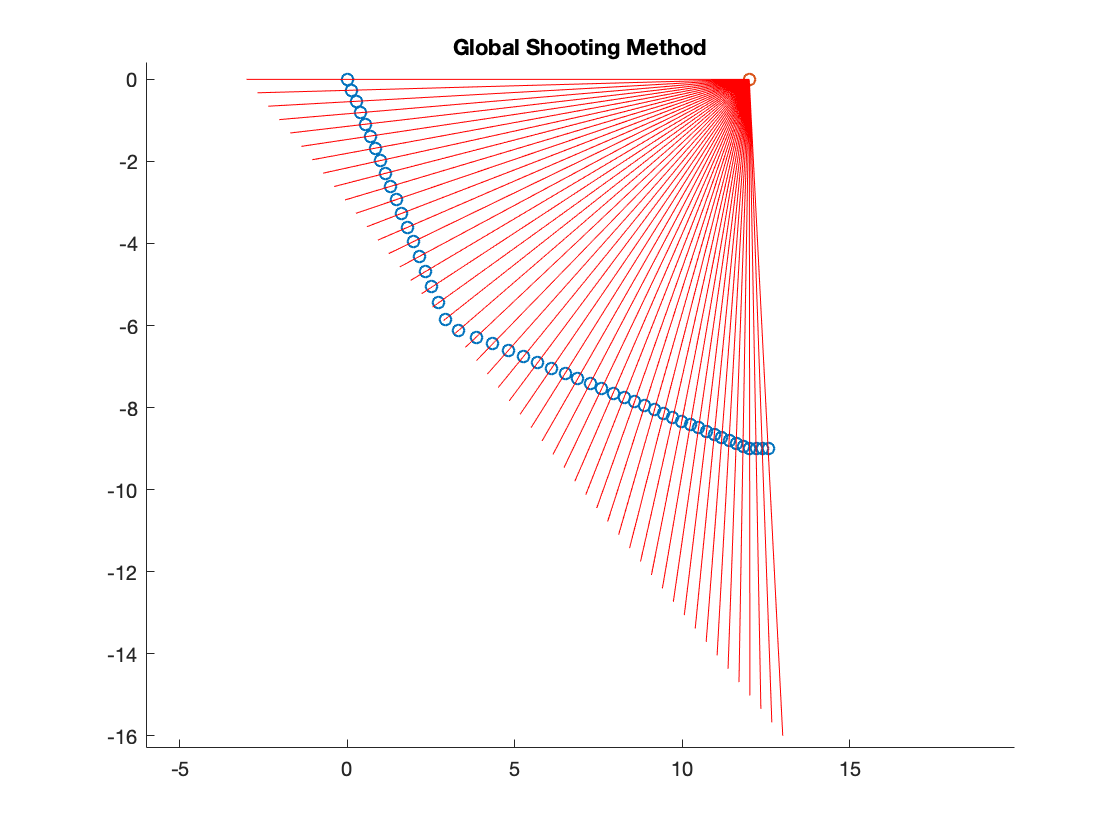

scatter(front(1,:), front(2, :))
hold on
scatter(ai(1), ai(2));

for i = 1:POINTS
    plot([q(1,i), ai(1)], [q(2,i), ai(2)], 'red');
end
title('Global Shooting Method');
xlim([-6.0 19.9])
ylim([-16.3 0.4])